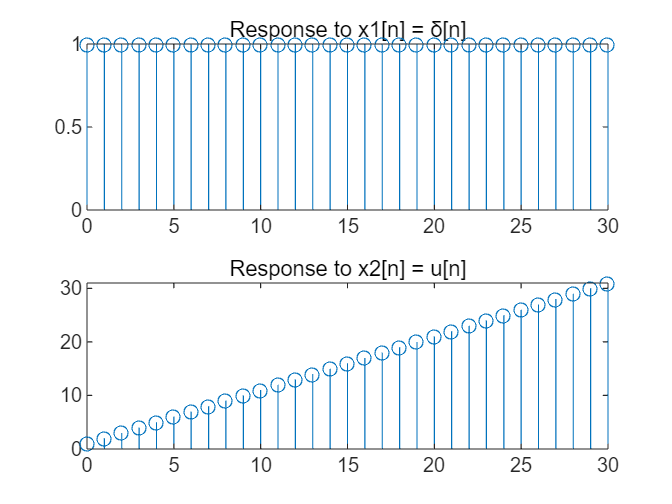

% 定义输入信号
N = 31; % 0≤n≤30
n = 0:N-1;
x1 = (n == 0); % 单位脉冲信号
x2 = ones(1, N); % 单位阶跃信号

% 计算响应
a = 1;
yn1 = 0; % y[-1]
y1 = diffeqn(a, x1, yn1);
y2 = diffeqn(a, x2, yn1);

% 绘制响应
figure;
subplot(2,1,1);
stem(0:N-1, y1);
title('Response to x1[n] = δ[n]');
subplot(2,1,2);
stem(0:N-1, y2);
title('Response to x2[n] = u[n]');